# Dimensionality reduction

The training examples in "split.mat" contains 31 features:

clear all;
load('split.mat', 'train_examples');

Use Principal Components Analysis to investigate reducing the dimensionality of the resulting feature space.

Marks are available for:

- Applying appropriate pre-processing steps to the data [4 marks]

- Recovering the principal components, and the transformed data [4 marks]

- Taking sensible steps to decide on how many principle components to retain [6 marks]

- Creating the new lower-dimensional dataset [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

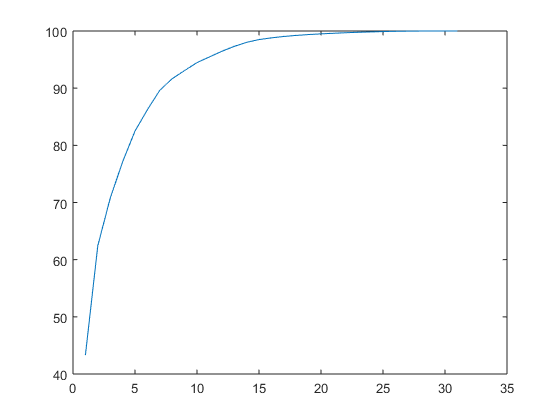

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31]
              YData: [1×31 double]
              ZData: [1×0 double]

  Show all properties


% add as many lines of code as you need below:

% start of standardisation process
mean = mean(train_examples{:,:});
std = std(train_examples{:,:});
for i=1:size(train_examples,1)
    train_examples{i,:} = train_examples{i,:} - mean;
    train_examples{i,:} = train_examples{i,:} ./ std;
end
% end of standardisation process

data = table2array(train_examples);
[principal_components, data_transformed, ~, ~, explained] = pca(data);
p = plot(cumsum(explained))


m = cumsum(explained);
pcs = 1;
for i=1:size(cumsum(explained))
    if m(i) >= 95
        pcs = i;
        break;
    end
end

pcs = 11

pcs

pcs = 11


data_reduced = data_transformed(:, 1:1:pcs);
